M = rand(16,16)

M =     0.6155    0.8611    0.9861    0.6862    0.0836    0.1214    0.7954    0.6366    0.5629    0.9138    0.0637    0.8687    0.3958    0.9571    0.4324    0.4654
    0.9189    0.2099    0.2072    0.3767    0.5127    0.5437    0.4927    0.5709    0.1767    0.6406    0.4255    0.5286    0.0849    0.4399    0.5051    0.0219
    0.6025    0.3991    0.7571    0.5043    0.8329    0.3146    0.3546    0.9271    0.5137    0.6588    0.4043    0.9141    0.2145    0.6015    0.3753    0.8083
    0.7021    0.8879    0.8863    0.7635    0.9046    0.3820    0.7751    0.8638    0.5485    0.6753    0.4003    0.9739    0.2488    0.7203    0.4804    0.1792
    0.7437    0.2565    0.4722    0.0489    0.7236    0.7915    0.2368    0.1698    0.1653    0.7446    0.1119    0.5854    0.2267    0.6788    0.3424    0.1654
    0.3851    0.9668    0.1589    0.7259    0.3830    0.8392    0.8448    0.1787    0.4939    0.8422    0.4243    0.1190    0.7030    0.2128    0.7771    0.1816
    0.2515    0.6192    0.8109

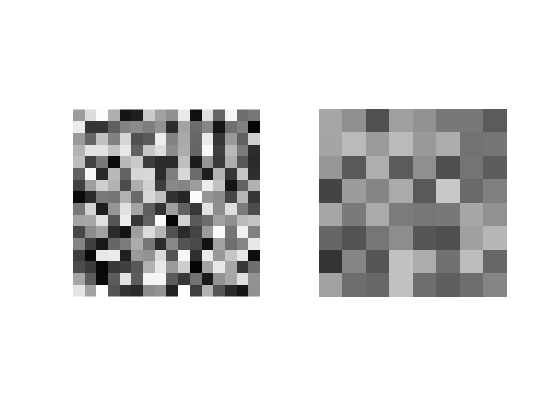

bigM = imresize(M,'nearest','OutputSize',[160,160]);
subplot(1,2,1)
imshow(bigM)
M2 = bigM;
k=20;
for i = 1:k:160
    for j = 1:k:160
        avg = mean(bigM(i:(i+k-1),j:(j+k-1)));
        avg = mean(avg);
        M2(i:(i+k-1),j:(j+k-1)) = repmat(avg, k, k);
    end
end
%smallM = imresize(M,'nearest','OutputSize',[8,8])
subplot(1,2,2)
%imshow(imresize(smallM,'nearest','OutputSize',[160,160]))
imshow(M2)